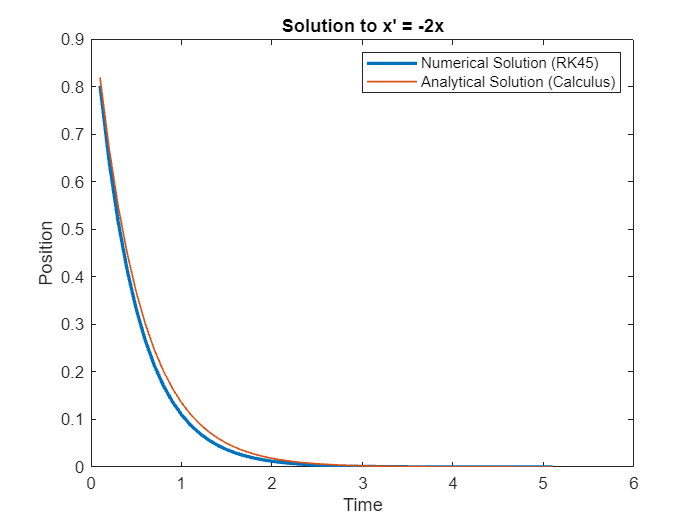

clear, clc, close all;

% RK45 Assignment
% Joseph Park
% Dec 6, 2024

% Step 1: Define the Function
function [RK45_t, RK45_x] = RK45(f, x0, t0, t_stop, dt, err_tol)
    % f: anonymous function representing the ODE (i = f(t,x))
    % x0: initial state
    % t0: initial time
    % t_stop: stopping time
    % dt: initial time step size
    % err_tol: error tolerance to control adaptive step-sizing
    
    % Step 2: Butcher Tableau Cofefficients
    load('rk45_coeffs.mat');

    % Step 3: Initialize Time and State Arrays
    t = t0; % Changed from set t intervals using dt, but changed after realizing dt is variable
    x = x0;
    RK45_t = t0:dt:t_stop;
    RK45_x = zeros(size(RK45_t));
    count = 1;

    % Step 4: Main Integration Loop
    while t < t_stop % Changed from a for loop, looping through constant intervals of t, but then, again, realized dt is variable.
        % {1} Compute the Runge-Kutta Stages
        k = zeros(size(x,1),7);
        for i = 1:7
            k(:,i) = dt * f(t + a(i) * dt, x + dt * sum(b(i, 1:i-1) .* k(:, 1:i-1), 2));
        end

        % {2} Compute the 4th and 5th-Order Estimates
        x_step = x + sum(c4 .* k, 2);
        z_step = x + sum(c5 .* k, 2);

        % {3} Estimate the Error
        err = max(abs(z_step - x_step));

        % {4} Adjust the Step Size
        if (err >= err_tol)
            dt = dt * min(max((err_tol/err)^(1/5),0.1),5.0);
        end
        
        % {5} Prevent Infinitesimal Step Sizes
        if (dt < eps)
            error("Step size too small. Solution might be diverging.");
            return;
        end

        % Step 5: Store Results
        t = t + dt;
        x = x_step;
        RK45_t(count) = t;
        RK45_x(count) = x;
        count = count + 1;
    end
end

% Testing Your Algorithm
f = @(t, x) -2 * x;
x0 = 1;
t0 = 0;
t_stop = 5;
dt = 0.1;
tol = 10^(-6);
[RK45_t, RK45_x] = RK45(f, x0, t0, t_stop, dt, tol);


f_actual = @(t) exp(-2*t);
figure
plot(RK45_t, RK45_x, 'LineWidth', 2)
hold on;
plot(RK45_t, f_actual(RK45_t), 'LineWidth', 1)
xlabel("Time")
ylabel("Position")
title("Solution to x' = -2x")
legend("Numerical Solution (RK45)", "Analytical Solution (Calculus)")
hold off;